Controllo se è rimasta aperta la porta seriale

if( exist('STM32_ser') );
    delete(STM32_ser);
    clear STM32_ser;
end

Connetto alla seriale

porte_libere = serialportlist("available")

porte_libere = "COM8"

STM32_ser = serialport(porte_libere(end), 9600, Timeout=5);
configureTerminator(STM32_ser,"CR")
STM32_ser.flush;

Richiedo il buffer tramite char 'e'

STM32_ser.write('e','char');
vettore=read(STM32_ser,100,'uint16');
length(vettore)

ans = 100

display(vettore)

vettore =        16269       13494        9472        5463        2576        2145        4951       11133       20321       31106       41928       50842       56381       57480       53722       46265       35955       25085       14951        7313        2965        1987        3860        7566       11768       15189       17116       17322       15833       13542       10959        8962        7930        8133        9497       11269       12961       14238       14645       14226       13071       11620       10513        9658        9729       10118       11161       12235       13036       13523


Impostazione ordine di grandezza corretto

%for i=1:length(vettore)
%    vettore(i) = vettore(i)/1000;
%end

h=plot(vettore, '-O');

fprintf('Temperatura Media: %f°C',mean(vettore));

Temperatura Media: 14310.750000°C

fprintf('Sigma : %f',std(vettore));

Sigma : 10442.648072

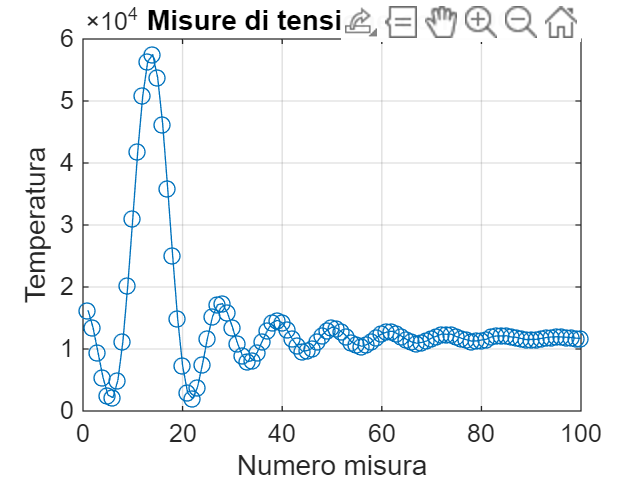

title('Misure di tensione con ADC');
ylabel("Temperatura");
xlabel('Numero misura');
box on
grid on